# System Identification: R&S Radio Communication Service Monitor

In un sistema radio, l'informazione viene trasmessa attraverso un segnale in radiofrequenza modulato, che è generato dalla modulazione della portante RF con un segnale di bassa frequenza modulante come un segnale audio.

Il Rohde & Schwarz Radio Communication Service Monitor è uno strumento versatile utilizzato come sistema radio per la trasmissione dei segnali in modalità di prova. Questo strumento è in grado di generare segnali RF a diverse frequenze e modulazioni, consentendo di testare la funzionalità dei dispositivi radio. Grazie alla sua flessibilità, il Rohde & Schwarz Radio Communication Service Monitor è uno strumento di riferimento ampiamente utilizzato nel settore delle telecomunicazioni per la taratura e il collaudo dei sistemi radio.

## Strumentazione di misura

La strumentazione di misura utilizzata include: l'oscilloscopio Tektronix 2012B, un cavo USB, cavo jack e il software MATLAB. L’oscilloscopio utilizzato è un dispositivo di misura elettronico, il quale dispone di due canali di ingresso, consente di acquisire segnali con una frequenza massima di 100 MHz, a una velocità massima di campionamento di 1 GS/s e con una risoluzione verticale di 8 bit. Per acquisire i dati dal Tektronix 2012B, è stato utilizzato un collegamento tramite porta USB tra l'oscilloscopio e il computer. Ciò ha permesso al software Matlab tramite l’Instrument Control Toolbox di comunicare con l'oscilloscopio e di acquisire i dati dai canali di misura. Inoltre, tramite Matlab è possibile generare un segnale audio che viene riprodotto attraverso l'uscita jack del computer.

## **Procedura di misura**

Il generatore di radio frequenza è stato settato su valori di frequenza in MHz variabili con step di 10 MHz a partire da 5 MHz fino a 95 MHz.

Sull’oscilloscopio sono stati utilizzati i 2 canali di misura al fine di rilevare il segnale in bassa frequenza e il segnale in radio frequenza. In particolare, sul canale 1 si è rilevato il segnale prelevato all’uscita del sistema radio; sul canale 2 si è prelevato il segnale di bassa frequenza in ingresso al sistema.

L’ingresso in bassa frequenza è stato ottenuto tramite cavo audio collegato al PC. Quindi, tramite script Matlab è stato possibile generare un segnale audio nello stesso istante in cui Matlab inizia l’acquisizione dai due canali dell’oscilloscopio. Sono stati considerati diversi segnali in ingresso di durata pari a 5 secondi come:

- Segnale sweep: con frequenza variabile da 20 Hz a 20000 Hz;

- Segnale sinusoidale con frequenza pari a 800 Hz;

- Segnale sinusoidale con frequenza pari a 6660 Hz;

- Segnale sinusoidale con frequenza pari a 13000 Hz;

- Segnale sinusoidale con frequenza pari a 20 KHz;

- Segnale nullo;

- Rumore bianco;

- Handel: Gloria in Exelsis Deo;

## Analisi dei dati

Il dataset è composto da tre colonne: l'ampiezza del segnale portante, l'ampiezza del segnale in bassa frequenza utilizzato per modulare la portante e l'ampiezza del segnale in radio frequenza risultante dalla modulazione. 

I dati raccolti descrivono l'andamento nel tempo di quest'ultimo segnale, e la serie di dati misurati è composta da 8 serie che differiscono per le tipologie di segnale in bassa frequenza utilizzato per la modulazione. Il tempo di campionamento considerato è pari a $400\mu s$ , il quale ha permesso di misurare circa 10000 valori per ciascuna frequenza della radio frequenza portante.

### Ingressi:

clc;
clear;
% Segnale portante con frequenza: 
subdirectory = "55MHz"; 
% Segnale a bassa frequenza: 
directory = "Handel"; 

### Uscite:

Segnale in radio frequenza modulata in ampiezza dal segnale in bassa frequenza;

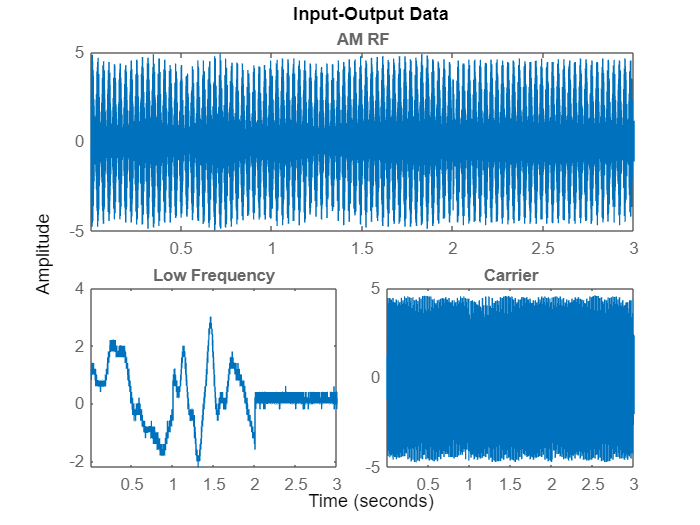

load(sprintf("%s/%s/data_iddataC.mat",directory,subdirectory));
plot(data);

Inoltre, è stato creato un dataset completo in cui sono state aggregate tutte le misure effettuate:

load("data_iddataAllC.mat")
plot(data)

## Ricerca dei dati chiave per il modello con il miglior Fit

Attraverso uno script matlab sono stati caricati dati da diverse cartelle ed elaborati con diversi modelli di analisi di sistema (come nlarx, armax e bj). Lo script restituisce il modello migliore in base a una soglia di fitness e in base al tipo di segnale in ingresso, il quale è poi memorizzato nella variabile maximum.

Il segnale di ingresso Sweep con frequenza di carrier a 65 MHz ha permesso di ottenere un fit del 93.6592 %, considerando 1000 campioni del dataset in un modello nlarx con:

- na = 4;

- nb = [4 4];

- nk = [1 1];

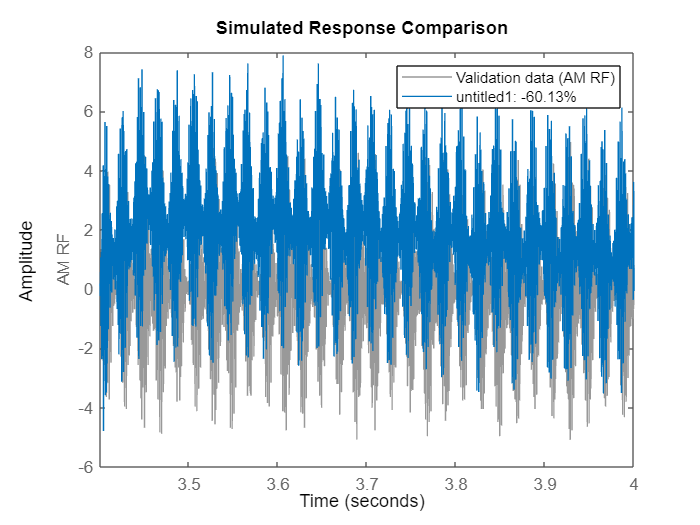

load("bestFit.mat");
load(sprintf("%s/%s/data_iddataC.mat",maximum.sig,maximum.freq));
data1000 = data(1:1000);
valid = data(8501:10000);
figure, compare(maximum.identified,valid)

m = maximum.identified

m =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 5 units
Sample time: 0.0004 seconds

Status:                                          
Estimated using NLARX on time domain data.       
Fit to estimation data: 93.66% (prediction focus)
FPE: 0.02011, MSE: 0.01932                       
More information in model's "Report" property.



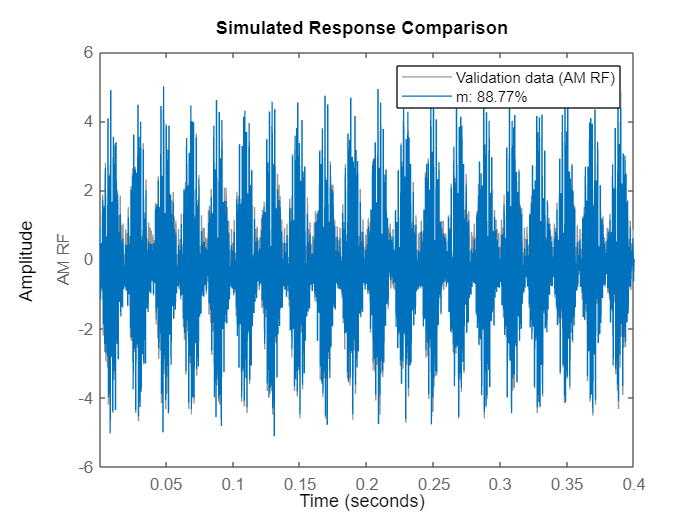

compare(m,data1000);

compare(m,valid);

## Identificazione con le altre famiglie di modelli

### Data Splitting

load("Segnale Sweep\65MHz\data_iddataC.mat");
data500 = data(1:500);
data1000 = data(1:1000);
data2000 = data(1:2000);
data5500 = data(1:5500);
data8500 = data(1:8500);
valid = data(8501:10000);

### ARX

#### Caso 1:

na = 2;
nb = 2*ones(1,2);
nk = 1*ones(1,2);
m1_500 = arx(data500,[na nb nk])

m1_500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 + 0.209 z^-1 + 0.1244 z^-2              
                                                   
                                                   
B1(z) = -0.01156 z^-1 + 0.009756 z^-2              
                                                   
  B2(z) = -1.091 z^-1 - 0.291 z^-2                 
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nk=[1 1]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARX on time domain data "data500".
Fit to estimation data: 86.87% (prediction focus) 
FPE: 0.08836, MSE: 0.08558                        
 


m1_1000 = arx(data1000,[na nb nk])

m1_1000 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
 A(z) = 1 + 0.2365 z^-1 + 0.1402 z^-2              
                                                   
  B1(z) = 0.02688 z^-1 - 0.03056 z^-2              
                                                   
  B2(z) = -1.073 z^-1 - 0.2975 z^-2                
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nk=[1 1]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data1000".
Fit to estimation data: 86.55% (prediction focus)  
FPE: 0.08838, MSE: 0.08698                         
 


m1_2000 = arx(data2000,[na nb nk])

m1_2000 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
 A(z) = 1 + 0.2388 z^-1 + 0.1247 z^-2              
                                                   
  B1(z) = 0.04024 z^-1 - 0.04408 z^-2              
                                                   
  B2(z) = -1.056 z^-1 - 0.3043 z^-2                
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nk=[1 1]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data2000".
Fit to estimation data: 86.9% (prediction focus)   
FPE: 0.07839, MSE: 0.07777                         
 


m1_5500 = arx(data5500,[na nb nk])

m1_5500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 + 1.123 z^-1 + 0.5709 z^-2              
                                                   
                                                   
B1(z) = -0.003579 z^-1 - 0.00669 z^-2              
                                                   
  B2(z) = -0.2748 z^-1 - 0.2536 z^-2               
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nk=[1 1]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data5500".
Fit to estimation data: 46.37% (prediction focus)  
FPE: 1.328, MSE: 1.324                             
 


m1_8500 = arx(data8500,[na nb nk])

m1_8500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 + 1.079 z^-1 + 0.5348 z^-2              
                                                   
  B1(z) = 0.04232 z^-1 - 0.04948 z^-2              
                                                   
  B2(z) = -0.2629 z^-1 - 0.2183 z^-2               
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nk=[1 1]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data8500".
Fit to estimation data: 45.49% (prediction focus)  
FPE: 1.331, MSE: 1.328                             
 


#### Caso 2:

na = 4;
nb = 4*ones(1,2);
nk = 1*ones(1,2);
m1_500 = arx(data500,[na nb nk])

m1_500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 + 0.1846 z^-1 - 0.1817 z^-2             
          - 0.666 z^-3 - 0.06488 z^-4              
                                                   
                                                   
  B1(z) = -0.03687 z^-1 + 0.07409 z^-2             
         + 0.08233 z^-3 - 0.1121 z^-4              
                                                   
                                                   
  B2(z) = -1.064 z^-1 - 0.246 z^-2                 
          + 0.1031 z^-3 + 0.4512 z^-4              
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nk=[1 1]
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARX on time domain data "data500

m1_1000 = arx(data1000,[na nb nk])

m1_1000 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 + 0.1633 z^-1 - 0.174 z^-2              
         - 0.7224 z^-3 - 0.06243 z^-4              
                                                   
                                                   
  B1(z) = -0.04037 z^-1 + 0.05115 z^-2             
          + 0.09607 z^-3 - 0.102 z^-4              
                                                   
                                                   
  B2(z) = -1.066 z^-1 - 0.1952 z^-2                
          + 0.1253 z^-3 + 0.5161 z^-4              
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nk=[1 1]
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data1

m1_2000 = arx(data2000,[na nb nk])

m1_2000 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 + 0.1405 z^-1 - 0.1781 z^-2             
         - 0.7856 z^-3 - 0.03085 z^-4              
                                                   
                                                   
  B1(z) = -0.01478 z^-1 + 0.06449 z^-2             
          + 0.009489 z^-3 - 0.05831 z^-4           
                                                   
                                                   
  B2(z) = -1.075 z^-1 - 0.1697 z^-2                
          + 0.1633 z^-3 + 0.6414 z^-4              
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nk=[1 1]
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data2

m1_5500 = arx(data5500,[na nb nk])

m1_5500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 + 0.5523 z^-1 - 0.2196 z^-2             
            - 0.45 z^-3 + 0.3107 z^-4              
                                                   
                                                   
  B1(z) = -0.03381 z^-1 + 0.03309 z^-2             
          + 0.024 z^-3 - 0.02903 z^-4              
                                                   
                                                   
  B2(z) = -0.4074 z^-1 - 0.2238 z^-2               
            + 0.248 z^-3 + 0.412 z^-4              
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nk=[1 1]
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data5

m1_8500 = arx(data8500,[na nb nk])

m1_8500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 + 0.4859 z^-1 - 0.2305 z^-2             
          - 0.3751 z^-3 + 0.3926 z^-4              
                                                   
                                                   
  B1(z) = -0.003079 z^-1 + 0.0198 z^-2             
          - 0.01917 z^-3 - 0.002521 z^-4           
                                                   
                                                   
  B2(z) = -0.2334 z^-1 - 0.07061 z^-2              
          + 0.2278 z^-3 + 0.2802 z^-4              
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nk=[1 1]
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data8

### ARMAX

#### Caso 1:

na = 2;
nb = 2*ones(1,2);
nk = 1*ones(1,2);
nc = 1;
m1_500 =  armax(data500,[na nb nc nk])

m1_500 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
                                                         
A(z) = 1 + 0.6187 z^-1 + 0.07996 z^-2                    
                                                         
                                                         
 B1(z) = -0.01624 z^-1 + 0.01284 z^-2                    
                                                         
  B2(z) = -1.011 z^-1 - 0.683 z^-2                       
                                                         
  C(z) = 1 + 0.7939 z^-1                                 
                                                         
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nc=1
   nk=[1 1]
   Number of free coefficients: 7
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using ARMAX on time domain data "data500".
Fit to estimation data: 

m1_1000 = armax(data1000,[na nb nc nk])

m1_1000 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 + 0.5685 z^-1 + 0.103 z^-2                    
                                                         
                                                         
  B1(z) = -0.005382 z^-1 + 0.0005056 z^-2                
                                                         
  B2(z) = -1.013 z^-1 - 0.6174 z^-2                      
                                                         
  C(z) = 1 + 0.7811 z^-1                                 
                                                         
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nc=1
   nk=[1 1]
   Number of free coefficients: 7
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using ARMAX on time domain data "data1000".
Fit to estimation data: 88.34% (prediction focus)    
FPE: 0.06622, MSE: 0.0653

m1_2000 = armax(data2000,[na nb nc nk])

m1_2000 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
                                                         
A(z) = 1 + 0.5317 z^-1 + 0.09471 z^-2                    
                                                         
                                                         
 B1(z) = -0.0124 z^-1 + 0.007692 z^-2                    
                                                         
  B2(z) = -1.009 z^-1 - 0.5834 z^-2                      
                                                         
  C(z) = 1 + 0.6534 z^-1                                 
                                                         
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nc=1
   nk=[1 1]
   Number of free coefficients: 7
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using ARMAX on time domain data "data2000".
Fit to estimation dat

m1_5500 = armax(data5500,[na nb nc nk])

m1_5500 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 + 1.495 z^-1 + 0.8988 z^-2                    
                                                         
                                                         
 B1(z) = -0.04405 z^-1 + 0.02858 z^-2                    
                                                         
  B2(z) = -0.0553 z^-1 - 0.04962 z^-2                    
                                                         
  C(z) = 1 + 0.8426 z^-1                                 
                                                         
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nc=1
   nk=[1 1]
   Number of free coefficients: 7
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using ARMAX on time domain data "data5500".
Fit to estimation data: 58.89% (prediction focus)    
FPE: 0.78, MSE: 0.778    

m1_8500 = armax(data8500,[na nb nc nk])

m1_8500 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 + 1.485 z^-1 + 0.8885 z^-2                    
                                                         
                                                         
 B1(z) = -0.02439 z^-1 + 0.01346 z^-2                    
                                                         
  B2(z) = -0.05665 z^-1 - 0.0522 z^-2                    
                                                         
  C(z) = 1 + 0.8422 z^-1                                 
                                                         
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nc=1
   nk=[1 1]
   Number of free coefficients: 7
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using ARMAX on time domain data "data8500".
Fit to estimation data: 58.59% (prediction focus)    
FPE: 0.7676, MSE: 0.7664 

#### Caso 2:

na = 4;
nb = 4*ones(1,2);
nk = 1*ones(1,2);
nc = 1;
m1_500 =  armax(data500,[na nb nc nk])

m1_500 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
                                                         
  A(z) = 1 + 0.352 z^-1 - 0.1843 z^-2                    
         - 0.7239 z^-3 - 0.09232 z^-4                    
                                                         
                                                         
  B1(z) = -0.04451 z^-1 + 0.07795 z^-2                   
          + 0.2048 z^-3 - 0.2302 z^-4                    
                                                         
                                                         
  B2(z) = -1.066 z^-1 - 0.4118 z^-2                      
         + 0.09132 z^-3 + 0.5088 z^-4                    
                                                         
  C(z) = 1 + 0.2816 z^-1                                 
                                                         
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nc=1
   nk=[1 1]
   Number of

m1_1000 = armax(data1000,[na nb nc nk])

m1_1000 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
                                                         
  A(z) = 1 + 0.3094 z^-1 - 0.1926 z^-2                   
         - 0.7546 z^-3 - 0.08978 z^-4                    
                                                         
                                                         
  B1(z) = -0.03615 z^-1 + 0.0187 z^-2                    
         + 0.0822 z^-3 - 0.05957 z^-4                    
                                                         
                                                         
  B2(z) = -1.067 z^-1 - 0.3404 z^-2                      
          + 0.1349 z^-3 + 0.5515 z^-4                    
                                                         
  C(z) = 1 + 0.3063 z^-1                                 
                                                         
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nc=1
   nk=[1 1]
   Number o

m1_2000 = armax(data2000,[na nb nc nk])

m1_2000 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
                                                         
  A(z) = 1 + 0.3241 z^-1 - 0.1811 z^-2                   
         - 0.8064 z^-3 - 0.05742 z^-4                    
                                                         
                                                         
  B1(z) = -0.009209 z^-1 + 0.04879 z^-2                  
        + 0.01183 z^-3 - 0.05079 z^-4                    
                                                         
                                                         
  B2(z) = -1.071 z^-1 - 0.3473 z^-2                      
          + 0.1564 z^-3 + 0.6664 z^-4                    
                                                         
  C(z) = 1 + 0.3767 z^-1                                 
                                                         
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nc=1
   nk=[1 1]
   Number o

m1_5500 = armax(data5500,[na nb nc nk])

m1_5500 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
                                                         
  A(z) = 1 + 0.9399 z^-1 + 0.06447 z^-2                  
         - 0.5246 z^-3 + 0.04231 z^-4                    
                                                         
                                                         
  B1(z) = -0.04906 z^-1 + 0.03914 z^-2                   
        + 0.01519 z^-3 - 0.01169 z^-4                    
                                                         
                                                         
  B2(z) = -0.5152 z^-1 - 0.3524 z^-2                     
           + 0.2237 z^-3 + 0.482 z^-4                    
                                                         
  C(z) = 1 + 0.6169 z^-1                                 
                                                         
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nc=1
   nk=[1 1]
   Number o

m1_8500 = armax(data8500,[na nb nc nk])

m1_8500 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
                                                         
  A(z) = 1 + 0.9567 z^-1 + 0.09627 z^-2                  
         - 0.4865 z^-3 + 0.05775 z^-4                    
                                                         
                                                         
  B1(z) = -0.02253 z^-1 + 0.05405 z^-2                   
        - 0.01536 z^-3 - 0.02227 z^-4                    
                                                         
                                                         
  B2(z) = -0.3432 z^-1 - 0.1568 z^-2                     
          + 0.2829 z^-3 + 0.4046 z^-4                    
                                                         
  C(z) = 1 + 0.6678 z^-1                                 
                                                         
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nc=1
   nk=[1 1]
   Number o

### BOX-JENKINS

#### Caso 1:

nb = 2*ones(1,2);
nf = 2*ones(1,2);
nc = 1;
nd = 1;
nk = 1*ones(1,2);
m1_500 =  bj(data500,[nb nf nc nd nk])

m1_500 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B1(z) = 2.295 z^-1 - 2.3 z^-2                                 
                                                                
  B2(z) = -0.8791 z^-1 - 1.181 z^-2                             
                                                                
                                                                
 C(z) = 1 + 0.2608 z^-1 + 0.1977 z^-2                           
                                                                
                                                                
 D(z) = 1 + 0.8643 z^-1 + 0.3419 z^-2                           
                                                                
  F1(z) = 1 + 0.09841 z^-1                                      
                                                                
  F2(z) = 1 + 0.8837 z^-1                                       
                                                                
Sample time: 0.0

m1_1000 = bj(data1000,[nb nf nc nd nk])

m1_1000 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B1(z) = 2.076 z^-1 - 2.079 z^-2                               
                                                                
  B2(z) = -0.8482 z^-1 - 1.222 z^-2                             
                                                                
                                                                
 C(z) = 1 + 0.3536 z^-1 + 0.2564 z^-2                           
                                                                
  D(z) = 1 + 1.19 z^-1 + 0.6239 z^-2                            
                                                                
  F1(z) = 1 + 0.3282 z^-1                                       
                                                                
  F2(z) = 1 + 0.8451 z^-1                                       
                                                                
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:
   nb=[2 

m1_2000 = bj(data2000,[nb nf nc nd nk])

m1_2000 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B1(z) = 2.389 z^-1 - 2.394 z^-2                               
                                                                
  B2(z) = -0.869 z^-1 - 1.145 z^-2                              
                                                                
                                                                
 C(z) = 1 + 0.2443 z^-1 + 0.1886 z^-2                           
                                                                
  D(z) = 1 + 1.193 z^-1 + 0.5666 z^-2                           
                                                                
  F1(z) = 1 + 0.4821 z^-1                                       
                                                                
  F2(z) = 1 + 0.8979 z^-1                                       
                                                                
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:
   nb=[2 

m1_5500 = bj(data5500,[nb nf nc nd nk])

m1_5500 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
                                                                
 B1(z) = -0.03236 z^-1 + 0.02643 z^-2                           
                                                                
  B2(z) = -0.5515 z^-1 + 0.4595 z^-2                            
                                                                
  C(z) = 1 + 1.194 z^-1 + 0.451 z^-2                            
                                                                
  D(z) = 1 + 1.566 z^-1 + 0.9863 z^-2                           
                                                                
  F1(z) = 1 + 0.5742 z^-1                                       
                                                                
  F2(z) = 1 - 0.5596 z^-1                                       
                                                                
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:
   nb=[2 

m1_8500 = bj(data8500,[nb nf nc nd nk])

m1_8500 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
                                                                
  B1(z) = -0.0001633 z^-1 + 0.0001361 z^-2                      
                                                                
  B2(z) = -0.3615 z^-1 - 0.3692 z^-2                            
                                                                
  C(z) = 1 + 1.267 z^-1 + 0.4596 z^-2                           
                                                                
  D(z) = 1 + 1.567 z^-1 + 0.9756 z^-2                           
                                                                
  F1(z) = 1 - 0.9902 z^-1                                       
                                                                
  F2(z) = 1 + 0.9861 z^-1                                       
                                                                
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:
   nb=[2 

#### Caso 2:

nb = 4*ones(1,2);
nf = 4*ones(1,2);
nc = 1;
nd = 1;
nk = 1*ones(1,2);
m1_500 =  bj(data500,[nb nf nc nd nk])

m1_500 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
                                                                
  B1(z) = 0.7973 z^-1 - 0.4791 z^-2                             
            - 1.516 z^-3 + 1.159 z^-4                           
                                                                
                                                                
  B2(z) = -1.042 z^-1 + 0.3766 z^-2                             
         + 0.07312 z^-3 - 0.2057 z^-4                           
                                                                
                                                                
  C(z) = 1 + 0.1027 z^-1 - 0.179 z^-2                           
          - 0.1977 z^-3 + 0.1674 z^-4                           
                                                                
                                                                
  D(z) = 1 + 0.7798 z^-1 - 0.336 z^-2                           
          - 0.79

m1_1000 = bj(data1000,[nb nf nc nd nk])

m1_1000 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
                                                                
  B1(z) = -2.153 z^-1 + 5.581 z^-2                              
                - 9.504 z^-3 + 6 z^-4                           
                                                                
                                                                
  B2(z) = -1.051 z^-1 + 0.4362 z^-2                             
         + 0.09408 z^-3 - 0.2097 z^-4                           
                                                                
                                                                
  C(z) = 1 - 0.4025 z^-1 - 0.2804 z^-2                          
          + 0.4851 z^-3 - 0.2963 z^-4                           
                                                                
                                                                
  D(z) = 1 + 0.6774 z^-1 - 0.6581 z^-2                          
          - 0.6

m1_2000 = bj(data2000,[nb nf nc nd nk])

m1_2000 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
                                                                
  B1(z) = 4.96 z^-1 - 9.468 z^-2                                
            + 11.69 z^-3 - 7.184 z^-4                           
                                                                
                                                                
  B2(z) = -1.062 z^-1 + 0.5232 z^-2                             
          + 0.1191 z^-3 - 0.1743 z^-4                           
                                                                
                                                                
  C(z) = 1 - 0.1773 z^-1 - 0.09784 z^-2                         
         + 0.07012 z^-3 - 0.1338 z^-4                           
                                                                
                                                                
  D(z) = 1 + 0.6425 z^-1 - 0.1907 z^-2                          
          - 0.3

m1_5500 = bj(data5500,[nb nf nc nd nk])

m1_5500 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
                                                                
  B1(z) = -0.0133 z^-1 + 0.05772 z^-2                           
        + 0.01037 z^-3 - 0.06088 z^-4                           
                                                                
                                                                
  B2(z) = -0.5071 z^-1 - 0.2973 z^-2                            
         + 0.1555 z^-3 - 0.02983 z^-4                           
                                                                
                                                                
  C(z) = 1 - 0.6045 z^-1 - 0.4279 z^-2                          
          + 0.5054 z^-3 + 0.2898 z^-4                           
                                                                
                                                                
  D(z) = 1 - 0.1166 z^-1 - 0.6411 z^-2                          
         - 0.09

m1_8500 = bj(data8500,[nb nf nc nd nk])

m1_8500 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
                                                                
  B1(z) = -0.0145 z^-1 + 0.04188 z^-2                           
         + 0.0103 z^-3 - 0.04204 z^-4                           
                                                                
                                                                
  B2(z) = -0.3352 z^-1 + 0.5573 z^-2                            
         - 0.1609 z^-3 - 0.06371 z^-4                           
                                                                
                                                                
  C(z) = 1 + 1.816 z^-1 + 1.356 z^-2                            
          + 0.7684 z^-3 + 0.3907 z^-4                           
                                                                
                                                                
  D(z) = 1 + 2.014 z^-1 + 1.656 z^-2                            
         + 0.41

### NARX

#### Caso 1:

na = 2;
nb = 2*ones(1,2);
nk = 1*ones(1,2);
m1_500 =  nlarx(data500,[na nb nk])

m1_500 =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 2 units
Sample time: 0.0004 seconds

Status:                                             
Estimated using NLARX on time domain data "data500".
Fit to estimation data: 87.65% (prediction focus)   
FPE: 0.07875, MSE: 0.07565                          
More information in model's "Report" property.

<a h

m1_1000 = nlarx(data1000,[na nb nk])

m1_1000 =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 14 units
Sample time: 0.0004 seconds

Status:                                              
Estimated using NLARX on time domain data "data1000".
Fit to estimation data: 88.15% (prediction focus)    
FPE: 0.07052, MSE: 0.06747                           
More information in model's "Report" 

m1_2000 = nlarx(data2000,[na nb nk])

m1_2000 =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 16 units
Sample time: 0.0004 seconds

Status:                                              
Estimated using NLARX on time domain data "data2000".
Fit to estimation data: 88.96% (prediction focus)    
FPE: 0.05654, MSE: 0.0552                            
More information in model's "Report" 

m1_5500 = nlarx(data5500,[na nb nk])

m1_5500 =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 23 units
Sample time: 0.0004 seconds

Status:                                              
Estimated using NLARX on time domain data "data5500".
Fit to estimation data: 49.11% (prediction focus)    
FPE: 1.206, MSE: 1.192                               
More information in model's "Report" 

m1_8500 = nlarx(data8500,[na nb nk])

m1_8500 =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 7 units
Sample time: 0.0004 seconds

Status:                                              
Estimated using NLARX on time domain data "data8500".
Fit to estimation data: 47% (prediction focus)       
FPE: 1.26, MSE: 1.255                                
More information in model's "Report" p

#### Caso 2:

na = 4;
nb = 4*ones(1,2);
nk = 1*ones(1,2);
m1_500 =  nlarx(data500,[na nb nk])

m1_500 =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 6 units
Sample time: 0.0004 seconds

Status:                                             
Estimated using NLARX on time domain data "data500".
Fit to estimation data: 92.88% (prediction focus)   
FPE: 0.0274, MSE: 0.02518                           
More information in model's "Report" property.

<a h

m1_1000 = nlarx(data1000,[na nb nk])

m1_1000 =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 5 units
Sample time: 0.0004 seconds

Status:                                              
Estimated using NLARX on time domain data "data1000".
Fit to estimation data: 93.66% (prediction focus)    
FPE: 0.02011, MSE: 0.01932                           
More information in model's "Report" p

m1_2000 = nlarx(data2000,[na nb nk])

m1_2000 =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 10 units
Sample time: 0.0004 seconds

Status:                                              
Estimated using NLARX on time domain data "data2000".
Fit to estimation data: 93.32% (prediction focus)    
FPE: 0.02074, MSE: 0.02023                           
More information in model's "Report" 

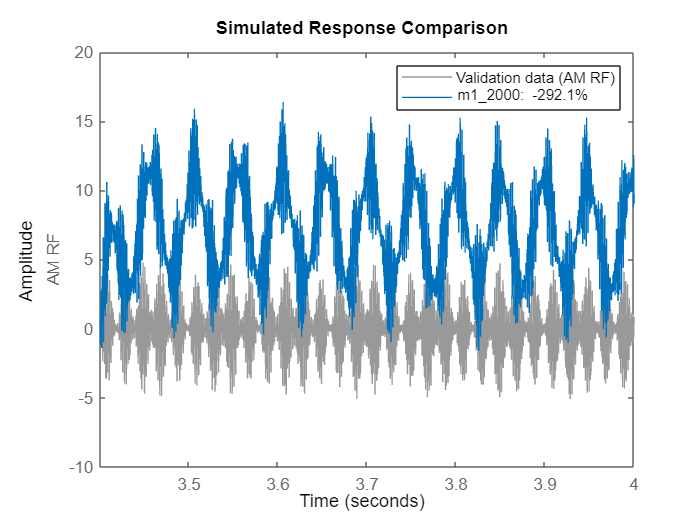

figure,compare(m1_2000,data2000)
figure,compare(m1_2000,valid)

m1_5500 = nlarx(data5500,[na nb nk])

m1_5500 =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 2 units
Sample time: 0.0004 seconds

Status:                                              
Estimated using NLARX on time domain data "data5500".
Fit to estimation data: 67.7% (prediction focus)     
FPE: 0.4833, MSE: 0.4803                             
More information in model's "Report" p

m1_8500 = nlarx(data8500,[na nb nk])

m1_8500 =

Nonlinear ARX model with 1 output and 2 inputs
  Inputs: Low Frequency, Carrier
  Outputs: AM RF

Regressors:
  Linear regressors in variables AM RF, Low Frequency, Carrier
  List of all regressors

Output function: Wavelet network with 1 units
Sample time: 0.0004 seconds

Status:                                              
Estimated using NLARX on time domain data "data8500".
Fit to estimation data: 64.82% (prediction focus)    
FPE: 0.5554, MSE: 0.5533                             
More information in model's "Report" p

### Data preprocessing and data splitting

load("Segnale Sweep\65MHz\data_iddataC.mat");
data = detrend(data,0)

data =

Time domain data set with 10000 samples.
Sample time: 0.0004 seconds              
                                         
Outputs             Unit (if specified)  
   AM RF                                 
                                         
Inputs              Unit (if specified)  
   Low Frequency                         
   Carrier                               
                                         


plot(data)
data500 = data(1:500);
data1000 = data(1:1000);
data2000 = data(1:2000);
data5500 = data(1:5500);
data8500 = data(1:8500);
valid = data(8501:10000);

### ARX

#### Caso 1:

na = 2;
nb = 2*ones(1,2);
nk = 1*ones(1,2);
m1_500 = arx(data500,[na nb nk])

m1_500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 + 0.209 z^-1 + 0.1244 z^-2              
                                                   
                                                   
B1(z) = -0.007906 z^-1 + 0.01344 z^-2              
                                                   
  B2(z) = -1.091 z^-1 - 0.291 z^-2                 
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nk=[1 1]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARX on time domain data "data500".
Fit to estimation data: 86.87% (prediction focus) 
FPE: 0.08834, MSE: 0.08556                        
 


m1_1000 = arx(data1000,[na nb nk])

m1_1000 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
 A(z) = 1 + 0.2364 z^-1 + 0.1403 z^-2              
                                                   
  B1(z) = 0.03005 z^-1 - 0.02745 z^-2              
                                                   
  B2(z) = -1.073 z^-1 - 0.2973 z^-2                
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nk=[1 1]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data1000".
Fit to estimation data: 86.55% (prediction focus)  
FPE: 0.08839, MSE: 0.08699                         
 


m1_2000 = arx(data2000,[na nb nk])

m1_2000 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
 A(z) = 1 + 0.2388 z^-1 + 0.1248 z^-2              
                                                   
  B1(z) = 0.0433 z^-1 - 0.04113 z^-2               
                                                   
  B2(z) = -1.055 z^-1 - 0.304 z^-2                 
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nk=[1 1]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data2000".
Fit to estimation data: 86.9% (prediction focus)   
FPE: 0.0784, MSE: 0.07777                          
 


m1_5500 = arx(data5500,[na nb nk])

m1_5500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 + 1.125 z^-1 + 0.5734 z^-2              
                                                   
                                                   
B1(z) = -0.005524 z^-1 - 0.01305 z^-2              
                                                   
  B2(z) = -0.2686 z^-1 - 0.2475 z^-2               
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nk=[1 1]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data5500".
Fit to estimation data: 46.45% (prediction focus)  
FPE: 1.324, MSE: 1.32                              
 


m1_8500 = arx(data8500,[na nb nk])

m1_8500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 + 1.079 z^-1 + 0.5355 z^-2              
                                                   
  B1(z) = 0.04155 z^-1 - 0.05111 z^-2              
                                                   
  B2(z) = -0.2609 z^-1 - 0.2163 z^-2               
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=2
   nb=[2 2]   nk=[1 1]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data8500".
Fit to estimation data: 45.49% (prediction focus)  
FPE: 1.331, MSE: 1.328                             
 


#### Caso 2:

na = 4;
nb = 4*ones(1,2);
nk = 1*ones(1,2);
m1_500 = arx(data500,[na nb nk])

m1_500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 + 0.1846 z^-1 - 0.1816 z^-2             
         - 0.6659 z^-3 - 0.06485 z^-4              
                                                   
                                                   
  B1(z) = -0.03502 z^-1 + 0.07604 z^-2             
         + 0.08419 z^-3 - 0.1103 z^-4              
                                                   
                                                   
  B2(z) = -1.064 z^-1 - 0.246 z^-2                 
          + 0.1031 z^-3 + 0.4512 z^-4              
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nk=[1 1]
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARX on time domain data "data500

m1_1000 = arx(data1000,[na nb nk])

m1_1000 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 + 0.1626 z^-1 - 0.1742 z^-2             
          - 0.7224 z^-3 - 0.0621 z^-4              
                                                   
                                                   
  B1(z) = -0.03897 z^-1 + 0.05273 z^-2             
         + 0.09732 z^-3 - 0.1008 z^-4              
                                                   
                                                   
  B2(z) = -1.066 z^-1 - 0.1944 z^-2                
          + 0.1258 z^-3 + 0.5164 z^-4              
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nk=[1 1]
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data1

m1_2000 = arx(data2000,[na nb nk])

m1_2000 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 + 0.1399 z^-1 - 0.1784 z^-2             
          - 0.7858 z^-3 - 0.0306 z^-4              
                                                   
                                                   
  B1(z) = -0.01406 z^-1 + 0.06523 z^-2             
        + 0.01008 z^-3 - 0.05771 z^-4              
                                                   
                                                   
  B2(z) = -1.075 z^-1 - 0.169 z^-2                 
          + 0.1638 z^-3 + 0.6417 z^-4              
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nk=[1 1]
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data2

m1_5500 = arx(data5500,[na nb nk])

m1_5500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 + 0.5521 z^-1 - 0.2184 z^-2             
          - 0.4478 z^-3 + 0.3126 z^-4              
                                                   
                                                   
  B1(z) = -0.03556 z^-1 + 0.03267 z^-2             
        + 0.02372 z^-3 - 0.03106 z^-4              
                                                   
                                                   
  B2(z) = -0.4041 z^-1 - 0.217 z^-2                
          + 0.2541 z^-3 + 0.4141 z^-4              
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nk=[1 1]
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data5

m1_8500 = arx(data8500,[na nb nk])

m1_8500 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 + 0.4861 z^-1 - 0.2307 z^-2             
          - 0.3756 z^-3 + 0.3923 z^-4              
                                                   
                                                   
  B1(z) = -0.004273 z^-1 + 0.02059 z^-2            
          - 0.01853 z^-3 - 0.005165 z^-4           
                                                   
                                                   
  B2(z) = -0.2311 z^-1 - 0.06505 z^-2              
          + 0.2334 z^-3 + 0.2826 z^-4              
                                                   
Sample time: 0.0004 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=[4 4]   nk=[1 1]
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data8

### ARMAX

#### Caso 1:

na = 2;
nb = 2*ones(1,2);
nk = 1*ones(1,2);
nc = 1;
m1_500 =  armax(data500,[na nb nc nk])
m1_1000 = armax(data1000,[na nb nc nk])
m1_2000 = armax(data2000,[na nb nc nk])
m1_5500 = armax(data5500,[na nb nc nk])
m1_8500 = armax(data8500,[na nb nc nk])

#### Caso 2:

na = 4;
nb = 4*ones(1,2);
nk = 1*ones(1,2);
nc = 1;
m1_500 =  armax(data500,[na nb nc nk])
m1_1000 = armax(data1000,[na nb nc nk])
m1_2000 = armax(data2000,[na nb nc nk])
m1_5500 = armax(data5500,[na nb nc nk])
m1_8500 = armax(data8500,[na nb nc nk])

### BOX-JENKINS

#### Caso 1:

nb = 2*ones(1,2);
nf = 2*ones(1,2);
nc = 1;
nd = 1;
nk = 1*ones(1,2);
m1_500 =  bj(data500,[nb nf nc nd nk])
m1_1000 = bj(data1000,[nb nf nc nd nk])
m1_2000 = bj(data2000,[nb nf nc nd nk])
m1_5500 = bj(data5500,[nb nf nc nd nk])
m1_8500 = bj(data8500,[nb nf nc nd nk])

#### Caso 2:

nb = 4*ones(1,2);
nf = 4*ones(1,2);
nc = 1;
nd = 1;
nk = 1*ones(1,2);
m1_500 =  bj(data500,[nb nf nc nd nk])
m1_1000 = bj(data1000,[nb nf nc nd nk])
m1_2000 = bj(data2000,[nb nf nc nd nk])
m1_5500 = bj(data5500,[nb nf nc nd nk])
m1_8500 = bj(data8500,[nb nf nc nd nk])

### NARX

#### Caso 1:

na = 2;
nb = 2*ones(1,2);
nk = 1*ones(1,2);
m1_500 =  nlarx(data500,[na nb nk])
m1_1000 = nlarx(data1000,[na nb nk])
m1_2000 = nlarx(data2000,[na nb nk])
m1_5500 = nlarx(data5500,[na nb nk])
m1_8500 = nlarx(data8500,[na nb nk])

#### Caso 2:

na = 4;
nb = 4*ones(1,2);
nk = 1*ones(1,2);
m1_500 =  nlarx(data500,[na nb nk])
figure,compare(m1_500,data500)
figure,compare(m1_500,valid)

m1_1000 = nlarx(data1000,[na nb nk])
figure,compare(m1_1000,data1000)
figure,compare(m1_1000,valid)
m1_2000 = nlarx(data2000,[na nb nk])
figure,compare(m1_2000,data2000)
figure,compare(m1_2000,valid)
m1_5500 = nlarx(data5500,[na nb nk])
m1_8500 = nlarx(data8500,[na nb nk])